# Task 2 - Semiconductor defect detection

## Read images

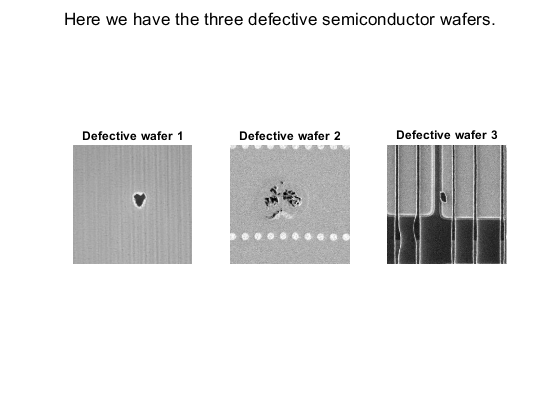

img_path = "images/final/task_2/";

image1 = imread(img_path + "defectivewafer1.jpg");
image2 = imread(img_path + "defectivewafer2.jpg");
image3 = imread(img_path + "defectivewafer3.jpg");

img1gray = rgb2gray(image1);
img2gray = rgb2gray(image2);
img3gray = rgb2gray(image3);

figure;
subplot(1, 3, 1); imshow(img1gray); title("Defective wafer 1");
subplot(1, 3, 2); imshow(img2gray); title("Defective wafer 2");
subplot(1, 3, 3); imshow(img3gray); title("Defective wafer 3");
sgtitle("Here we have the three defective semiconductor wafers.");

## Isolate Defects

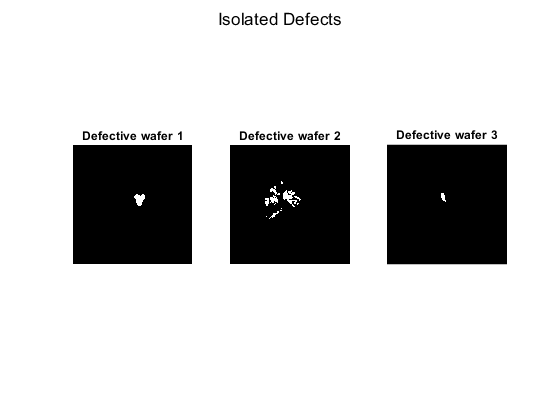

% First 2 images work with just default binarization
img1bw = imbinarize(img1gray);
img1bw_rev = imcomplement(img1bw);

img2bw = imbinarize(img2gray);
img2bw_rev = imcomplement(img2bw);

% Third image needs more filtering
img3bw = imbinarize(img3gray);
img3bw_rev = imcomplement(img3bw);
img3bw_clean = bwareafilt(img3bw_rev, [0 500]);
stel = strel('disk', 1);
img3bw_erode = imerode(img3bw_clean, stel);
img3bw_final = bwareaopen(img3bw_erode, 100);

figure;
subplot(1, 3, 1); imshow(img1bw_rev); title("Defective wafer 1");
subplot(1, 3, 2); imshow(img2bw_rev); title("Defective wafer 2");
subplot(1, 3, 3); imshow(img3bw_final); title("Defective wafer 3");
sgtitle("Isolated Defects"); 

## Draw circles

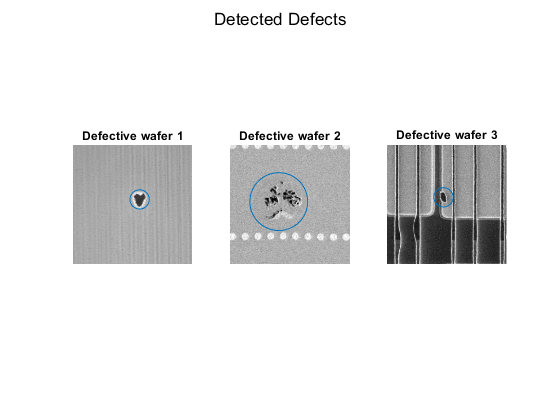

centroids_img1 = regionprops(img1bw_rev, 'Centroid');
centroids_1 = cat(1, centroids_img1.Centroid);
centroids_img2 = regionprops(img2bw_rev, 'Centroid');
centroids_2 = cat(1, centroids_img2.Centroid);
centroids_img3 = regionprops(img3bw_final, 'Centroid');
centroids_3 = cat(1, centroids_img3.Centroid);

figure;
circle_radius = 20;

subplot(1, 3, 1); imshow(image1); title("Defective wafer 1");
circle(centroids_1(:,1), centroids_1(:,2), circle_radius);

subplot(1, 3, 2); imshow(image2); title("Defective wafer 2");
% Image 2 has multiple centroids (detached shapes)
x_avg = mean(centroids_2(:,1));
y_avg = mean(centroids_2(:,2));
circle(x_avg, y_avg, circle_radius*3);

subplot(1, 3, 3); imshow(image3); title("Defective wafer 3");
circle(centroids_3(:,1), centroids_3(:,2), circle_radius);

sgtitle("Detected Defects");

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit);
    hold off
end

## Questions

**1. Which techniques did you use to solve this problem? Which one works the best? **

- Fo the first two images the defects were simply detected using the default binarization function, while the third image needed additional morph filtering in order to isolate it from the background. First, objects were removed from the binary image based on range of size. Second, the image was eroded based on a disk structural element and lastly, removed remaining small objects.

**2. How robust is your application? (When does it fail?)**

- The application would fail when a more complicated image like the third image happens to have artifacts that might be of a disk shape and size but is not a defective wafer.

**3. Could you make a common algorithm for all three images? Why/why not?**

- Not really. The first two images were fairly easy to compute, as only a simple binarization led to a clear showcase of the defect. The third image, however, needed some more filtering work before detecting the defect.

- It also happens that the defective wafer is split apart into different pieces, which might be recognized as noise during an isolating process.

**4. What are the extra parameters that you have computed to describe the defects?**

- The centroids of each wafer had to be retrieved, in order to calculate the object's center of mass based on the mean of its overall centroids.